# **Validación Modelo**

## Parámetros

%Pesos [N]
wb=0.105948;
wcp= 0.014145;
wm=0.030411; 

%Distancias [m]
d1=130.75e-3;
d2=50.75e-3;
e=41.91e-3;

%Momento de inercia [kg-m^2]
I=15e-5; 

%Coeficiente término \theta
Coeficiente = wcp*d2-wm*d1-wb*e;

%Constante del motor
km=0.001118;

%Constante de Fricción
beta = 1.667;
miu=beta*2*I;

%TransferFunction
% s=tf('s');
% c = (((wcp*d2-wm*d1-wb*e)/I)*(-cosd(thetap)));
% G=((km*d1)/I)/((s^2)+(miu/I)*s+(((wcp*d2-wm*d1-wb*e)/I)*(-cosd(thetap))));
% 
% 
% Gnum = cell2mat(G.Numerator);
% Gden = cell2mat(G.Denominator);

%Parametros del motor
DZ = 3;
MAX_PWM = 100;

## Cargado de datos experimentales 1 solo step

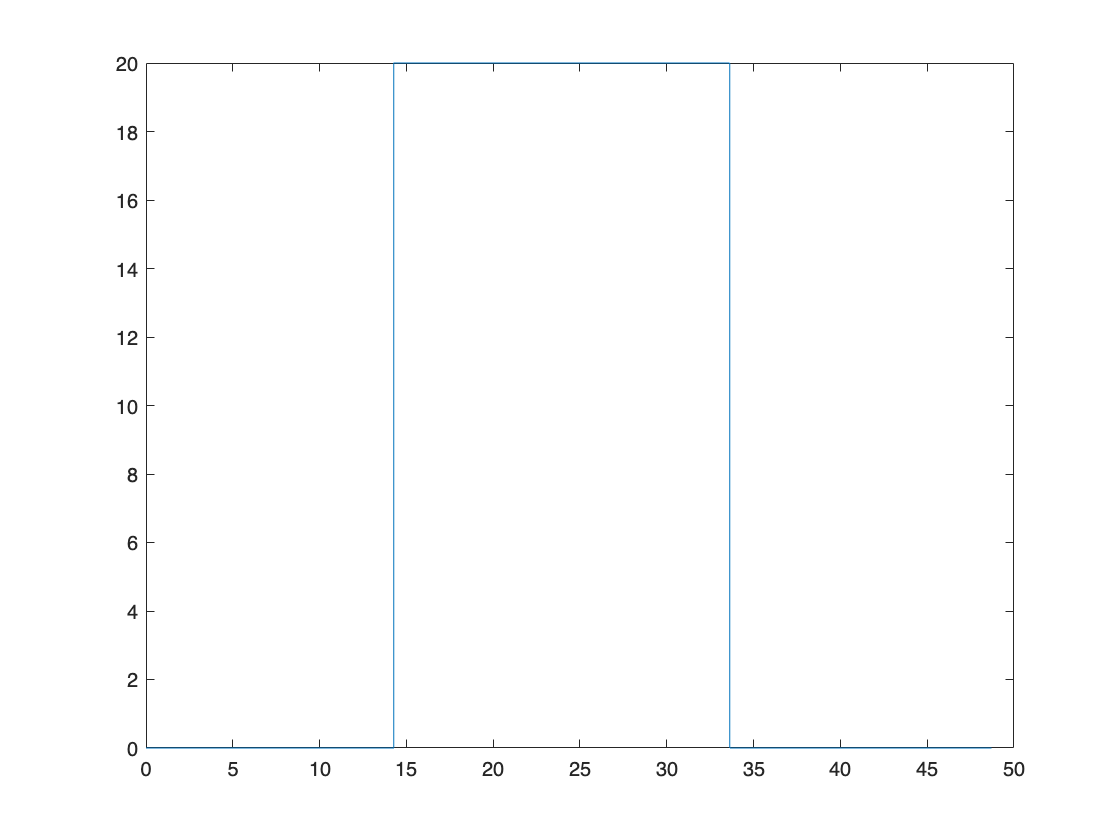

load("DatosStep02.mat");
Time = DatosStep02(:,1);
PWM = 100*DatosStep02(:,2);
Theta = DatosStep02(:,3);
plot(Time,PWM)

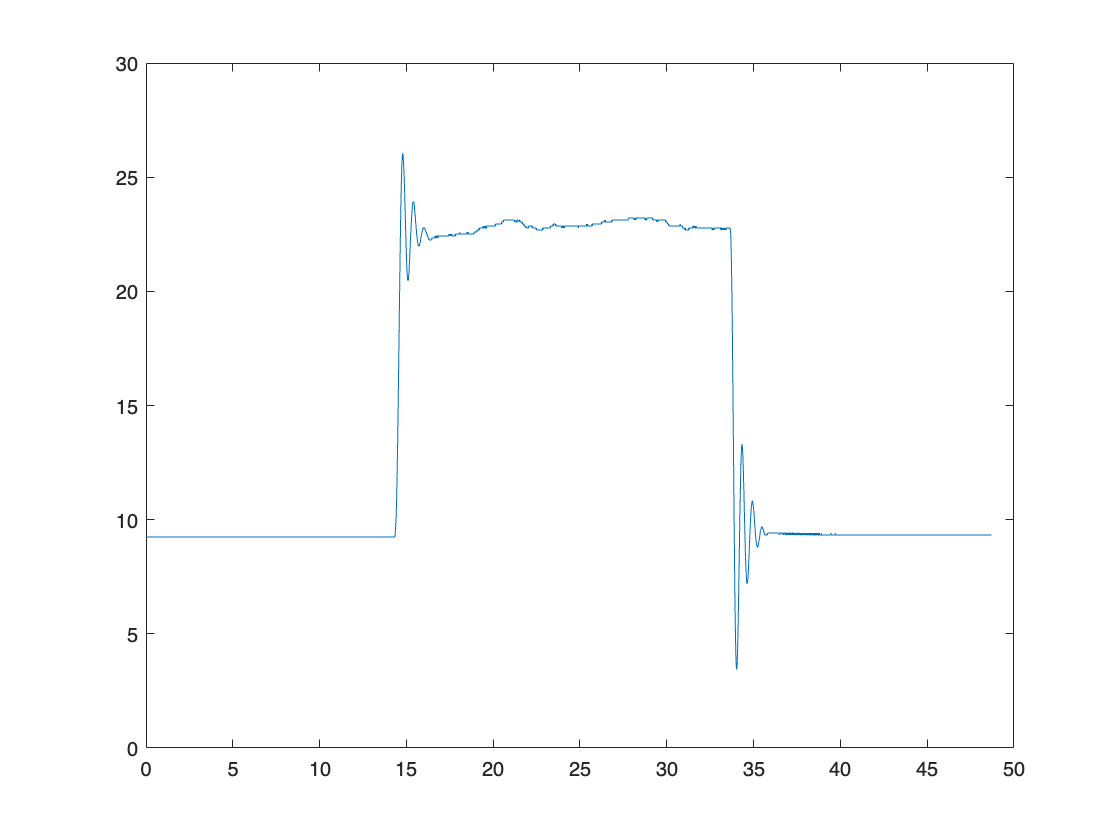

figure()
plot(Time,Theta)

## Cargado de datos experimentales varios step

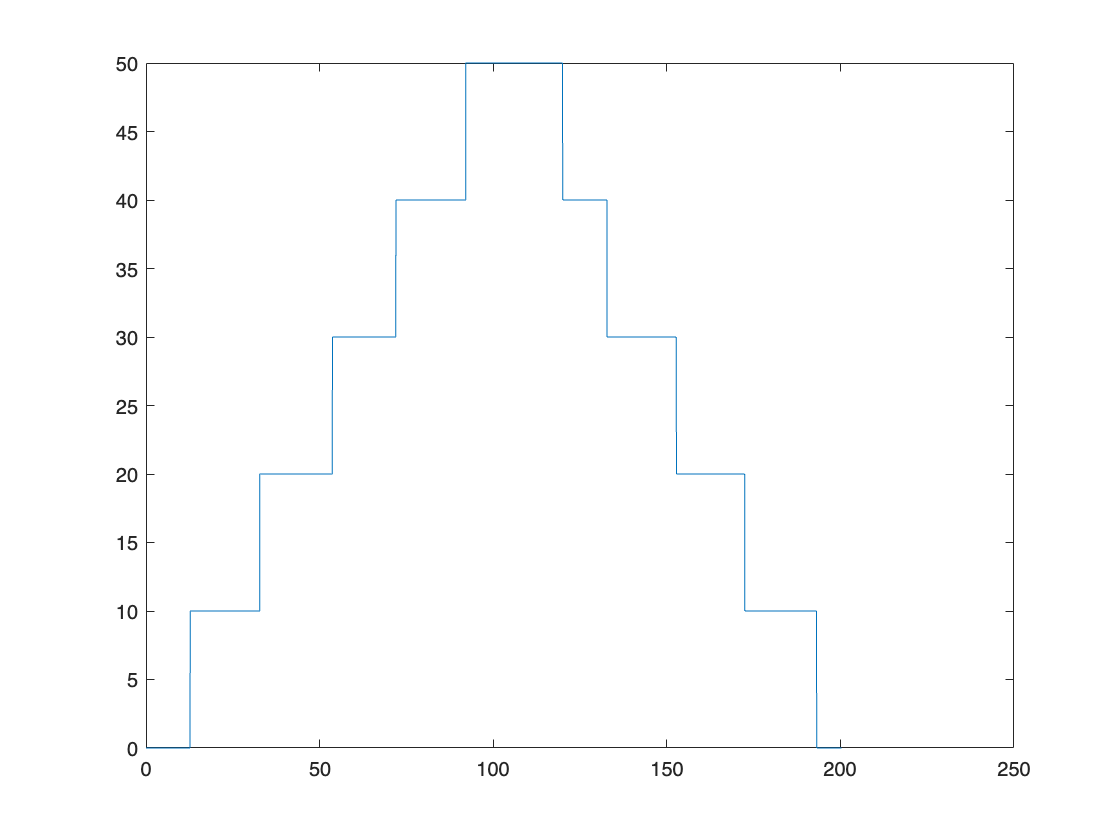

load("DatosStepsVariables.mat");
Time = DatosStepsVariables(:,1);
PWM = 100*DatosStepsVariables(:,2);
Theta = DatosStepsVariables(:,3);
plot(Time,PWM)

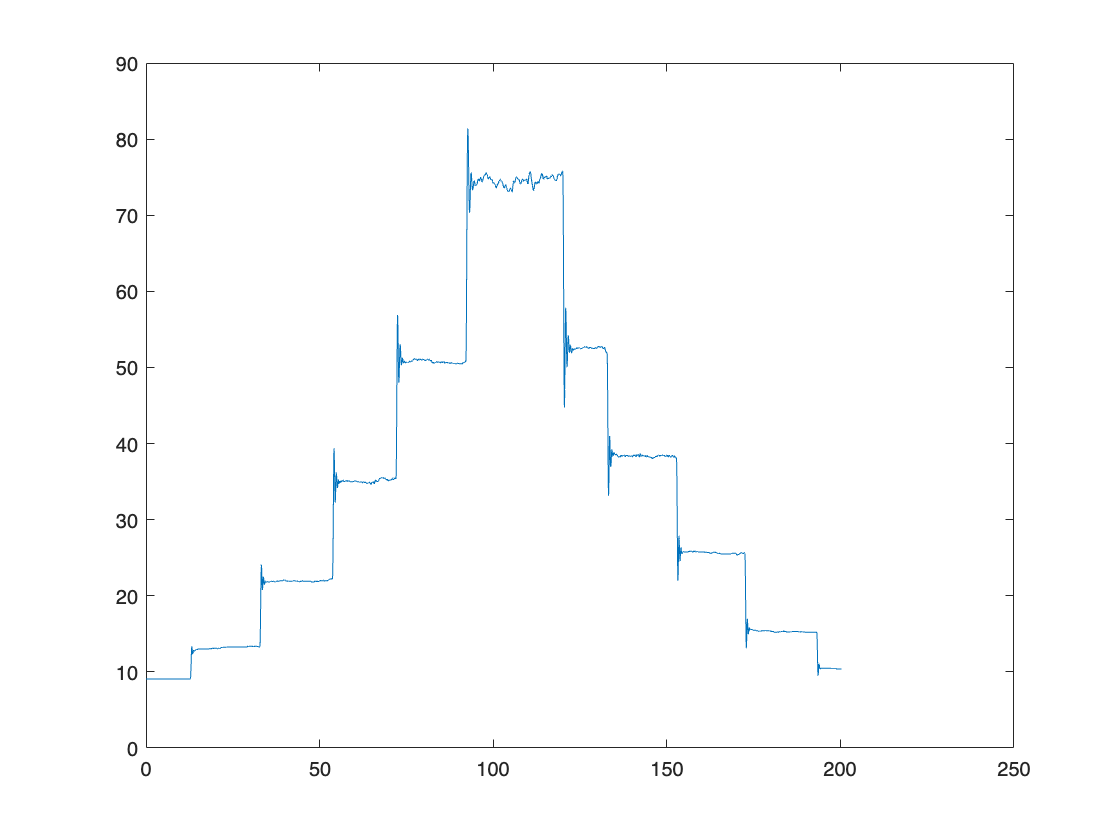

figure()
plot(Time,Theta)

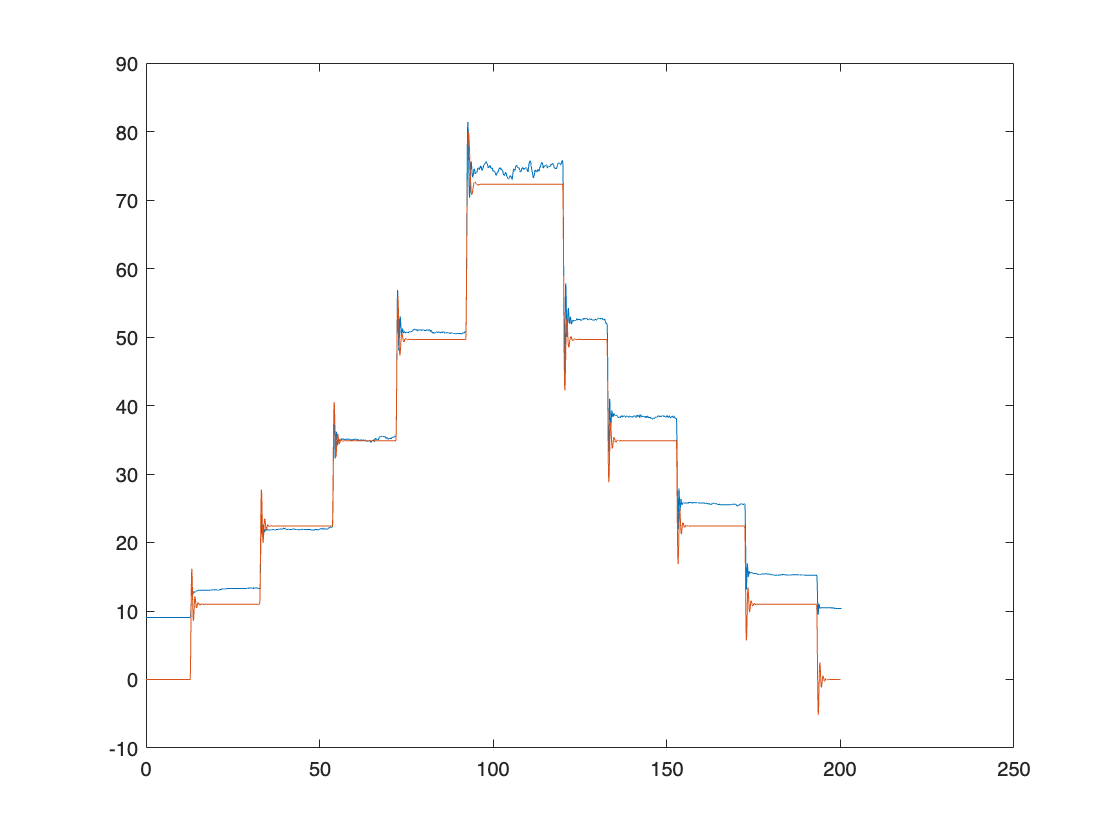

addpath("sims/")
simout = sim("plantaOpenLoop.slx", 200); % simluacion no lineal

t = simout.tout; 
y_nl = simout.nl_response.Data;

figure()
plot(Time,Theta)
hold on
plot(t,y_nl)
hold off